# Summary Results Demo

Use SummaryResults function to compare the costs values for the diferent states of the plant

#### Select and check the model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.xlsx";
data=ReadDataModel(filename);

#### Select the parameters

param=struct();
if data.isResourceCost
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
end

#### Obtain the Summary Results

res=SummaryResults(data,param);
printResults(res);

Summary Flows Exergy (kW)

 Key           REF    ETAT75    ETAC75    TCND35    TBLR85      W200
—————————————————————————————————————————————————————————————————————
 B1          620.8     637.8     620.8     694.0     641.4    1172.0
 B2          317.8     326.9     317.8     390.3     339.5     599.8
 B3          281.6     289.3     281.6     317.4     301.5     531.5
 B4          294.3     302.3     294.3     331.1     313.3     555.4
 B5          220.7     220.7     215.2     197.9     220.7     220.7
 B6          194.0     194.0     189.2     167.1     194.0     194.0
 B7           59.6      59.6      58.1      53.0      59.6      59.6
 B8          244.5     244.5     238.5     238.6     244.5     244.5
 WT          245.1     245.5     245.1     246.3     244.2     462.6
 WC          230.0     230.0     230.0     230.0     230.0     230.0
 WP           14.8      15.2      14.8      15.9      13.9      27.9
 QBLR        462.1     474.8     462.1     505.9     477.2     872.1
 QEVP 

#### Show the default summary results graph

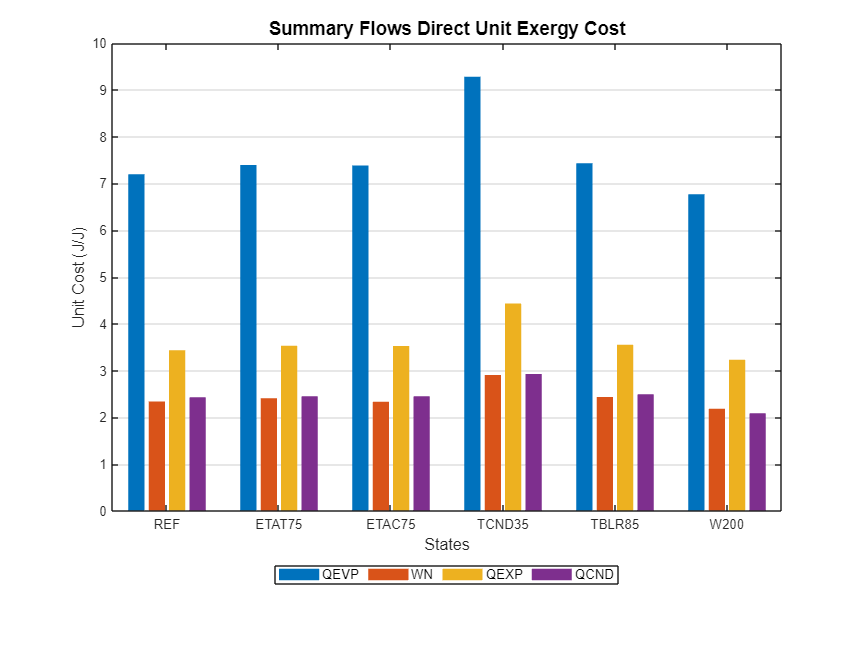

ShowGraph(res);